1 - Llegim la imatge i la posem en Gray

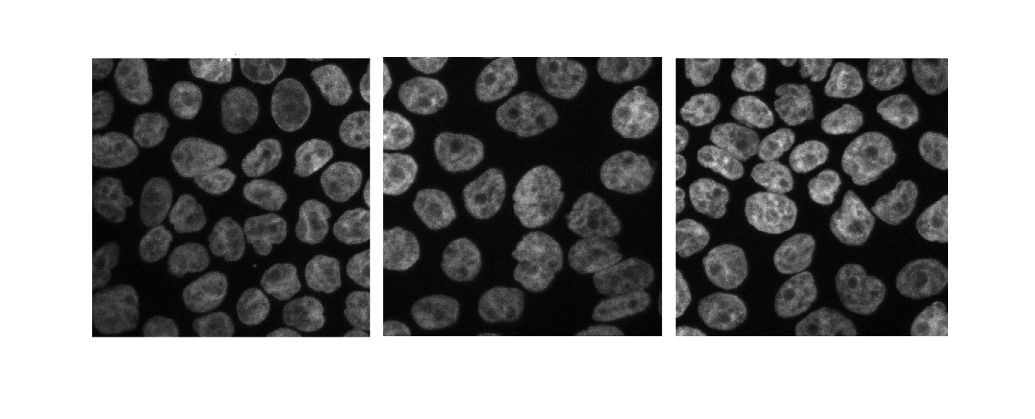

I = imread('cellsegmentationcompetition.png');
ndg = rgb2gray(I);
imshow(ndg);

2 - Posem els marcs de color negre per tal que siguin com el fons de la imatge

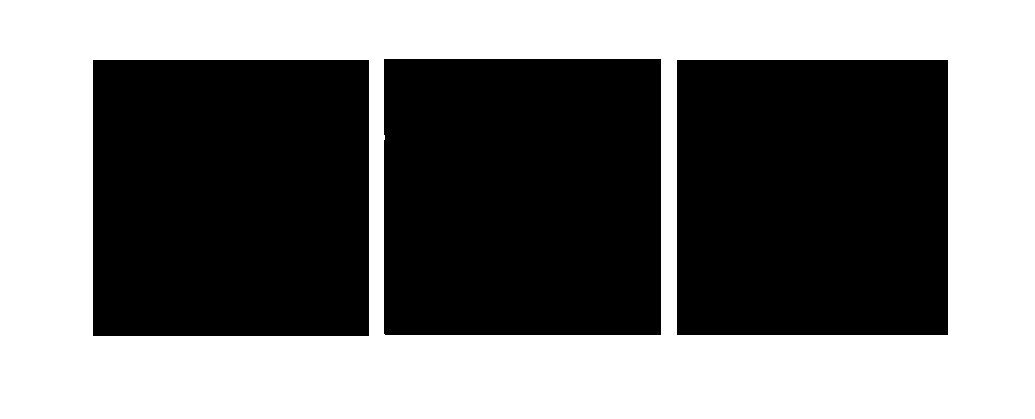

blancs = ndg > 250;
[F C] = size(ndg);
X = false(F,C);
X(1,:) = true;
X(end,:) = true;
X(:,1) = true;
X(:,end) = true;
D = imreconstruct(X, blancs);
SEh = strel('line', 6, 0);
SEv = strel('line', 8, 90);
A = imdilate(D, SEv);
A = imdilate(A, SEh);
imshow(A);

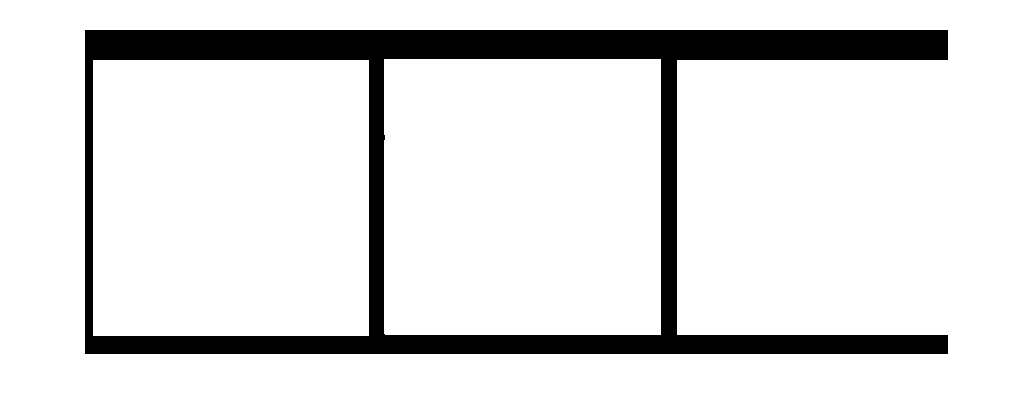

A = not(A);
A = uint8(A);
imshow(A, []);

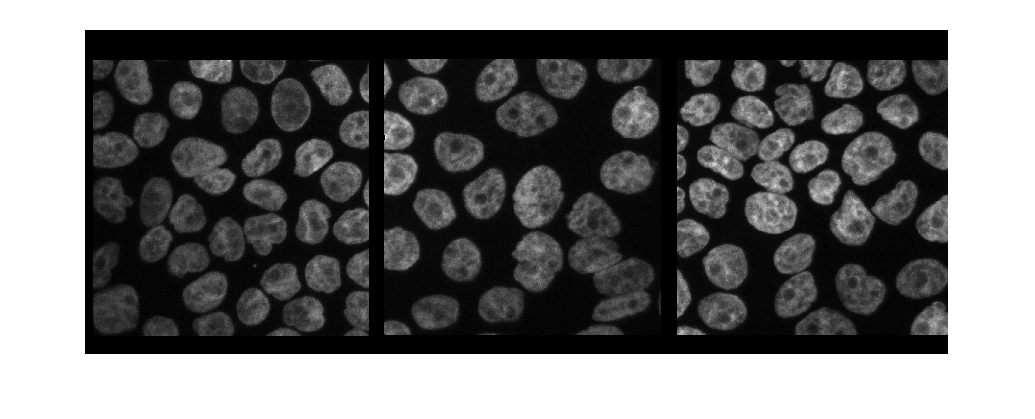

J = ndg .* A; 
imshow(J);

3 - Binaritzem la imatge i omplim els forats de les celules que estàn foradades, treiem el Foreground i el Background.

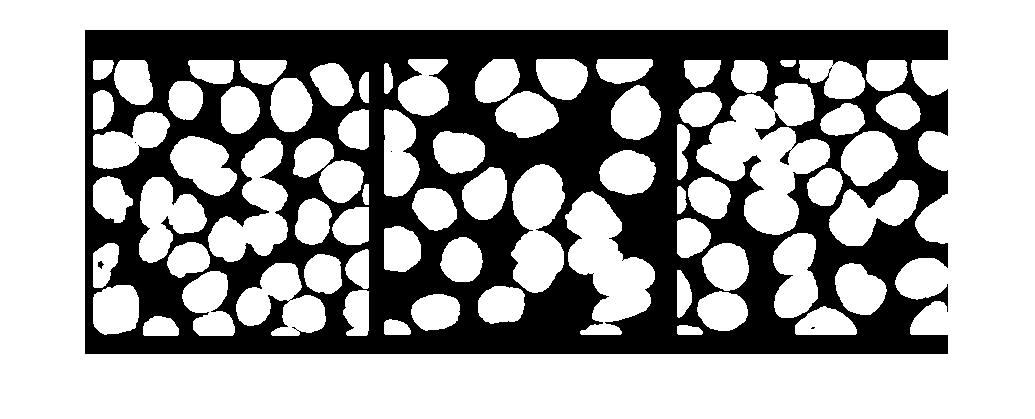

cellsize = 200;
SE = strel('disk', cellsize);
BW = J > 19;
IF = imtophat(BW, SE);
C = imopen(BW, strel('disk', 5));
imshow(C, []);

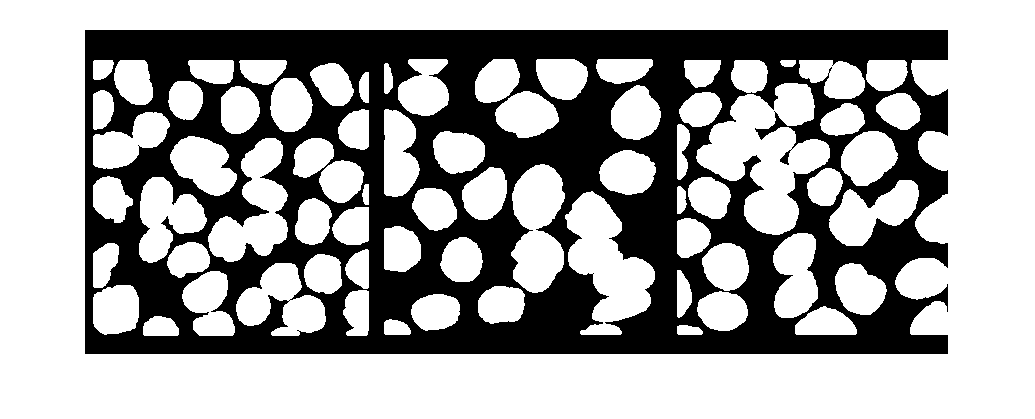

FG = imfill(C, 'holes');
imshow(FG, []);

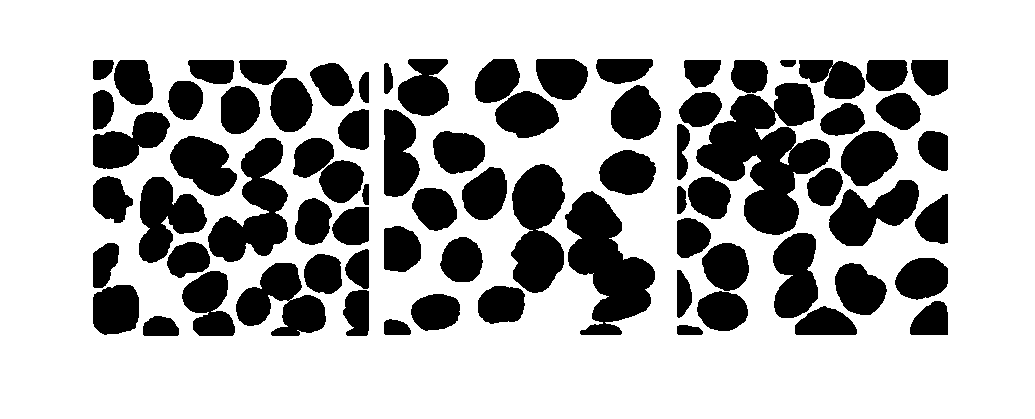

BG = not(FG);
imshow(BG, []);

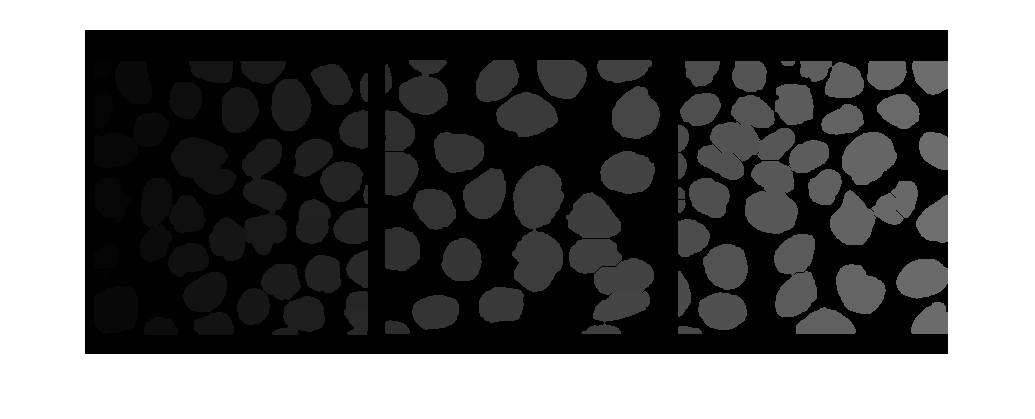

TD = bwdist(BG, 'euclidean');
TD = -TD;
TD(BG) = -Inf;
TDF = medfilt2(medfilt2(medfilt2(medfilt2(medfilt2(TD)))));
WS = watershed(TDF);
imshow(WS);

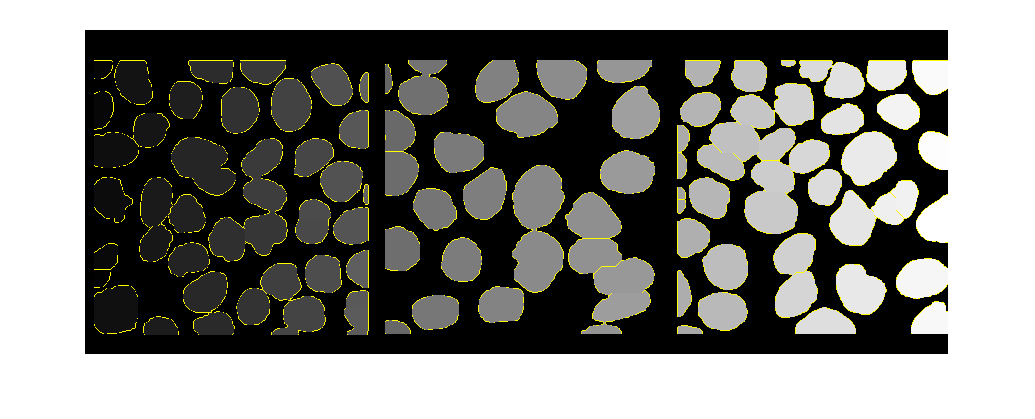

RGB = label2rgb(WS, 'gray', 'y');
imshow(RGB);